# Modelado de Sistemas Físicos

%Ejercicio para encontrar el tiempo que tarda un clavadista en llegar al mar. 

Segunda Ley de Newton

syms v(t) g cd m
eqn = diff(v,t) == g - (cd/m)*v^2

$$eqn(t) = \frac{\partial }{\partial t}v\left(t\right)=g-\frac{\mathrm{cd}\,{v\left(t\right)}^{2}}{m}$$

cond = v(0) == 0

$$cond = v\left(0\right)=0$$

vSym(t) = dsolve(eqn,cond)

$$vSym(t) = \frac{\sqrt{g}\,\sqrt{m}\,\tanh\left(\frac{\sqrt{\mathrm{cd}}\,\sqrt{g}\,t}{\sqrt{m}}\right)}{\sqrt{\mathrm{cd}}}$$

g = 9.81;
m = 68.1;
cd = 0.25;
vel = subs(vSym)

$$vel(t) = \frac{\sqrt{10}\,\sqrt{681}\,\sqrt{981}\,\tanh\left(\frac{\sqrt{10}\,\sqrt{681}\,\sqrt{981}\,t}{13620}\right)}{50}$$

tf = 12;
fplot(vel, [0,tf])
xlabel('t,s')
ylabel('v,m(s)')
grid on
title('Caída Libre')
hold on

#### Solución por el Método de Euler

t= 0:1:12

t =      0     1     2     3     4     5     6     7     8     9    10    11    12


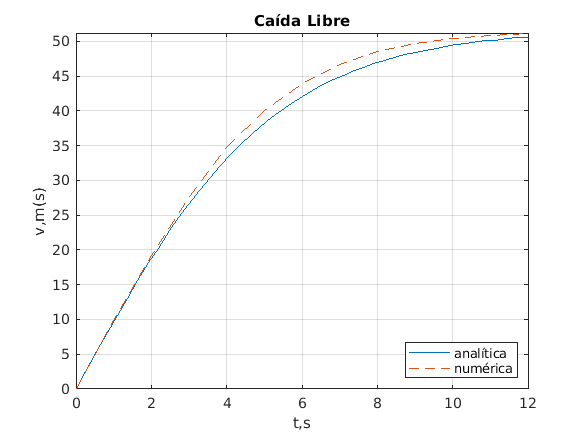

h=1;
a=@(v) g-(cd/m)*v^2; %funcion anónima
v= zeros(size(t));
for i=2:length(t)
     v(i)=v(i-1)+caidaLibre(g,cd,m,v(i-1))*h;
end
plot(t,v, '--')
legend('analítica', 'numérica')
legend('location', 'southeast')

syms x(t) x0 a v(t) v0;
eqn= diff(x,t,2)==a

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=a$$

Dx= diff(x,t);
cond = [x(0)==x0, Dx(0)==v0];
xSym(t) = dsolve(eqn,cond)

$$xSym(t) = \frac{a\,t^{2}}{2}+v_{0}\,t+x_{0}$$

v(t)= diff(xSym(t),t)

$$v(t) = v_{0}+a\,t$$

eqn = xSym(t)==0

$$eqn = \frac{a\,t^{2}}{2}+v_{0}\,t+x_{0}=0$$

tRoot= solve(eqn,t)

$$tRoot = \left(\begin{array}{c} -\frac{v_{0}-\sqrt{{v_{0}}^{2}-2\,a\,x_{0}}}{a}\\ -\frac{v_{0}+\sqrt{{v_{0}}^{2}-2\,a\,x_{0}}}{a} \end{array}\right)$$

a=-9.81;
x0=45;
v0=0;
double(subs(tRoot))

ans =   -3.028912664076914
   3.028912664076914


double(subs(v))*3600/1000

Error using symengine
Unable to convert expression into double array.

Error in sym/double (line 700)
        Xstr = mupadmex('symobj::double', S.s, 0);